# `ShowTaylor` calcula y muestra aproximaciones de polinomios de Taylor 

 Los argumentos son: 

-     `fh` , un identificador de función que identifica la función que se va a aproximar 

-     `deg` , el orden, o vector de órdenes, de los polinomios de Taylor que se utilizarán 

-     `bds` , un vector de longitud dos de dobles que identifica el dominio que se utilizará para trazar los resultados 

-     `x0` es un doble que identifica el centro, `x=x0` , de la aproximación del polinomio de Taylor 

 El valor de retorno es: 

- `T` , el polinomio de Taylor calculado de grado `deg` para la función `fh` alrededor de un punto central `x0`

`ShowTaylor` crea y muestra un gráfico de la función original y sus aproximaciones de orden `deg`. Si `deg` es un vector, entonces cada aproximación se muestra durante 0,2 segundos para animar la serie. Esto está destinado a usarse para observar cómo las aproximaciones mejoran con un orden creciente, pero no se limita a eso. 

##  Ejemplo 

`ShowTaylor(@cos,[3,7,15],[-2*pi 2*pi],0)` grafica la función $y=\cos(x)$ sobre el dominio $x \in [-2\pi,2\pi]$. Luego calcula los polinomios de Taylor de grado tres, siete y quince y produce tres gráficos: 

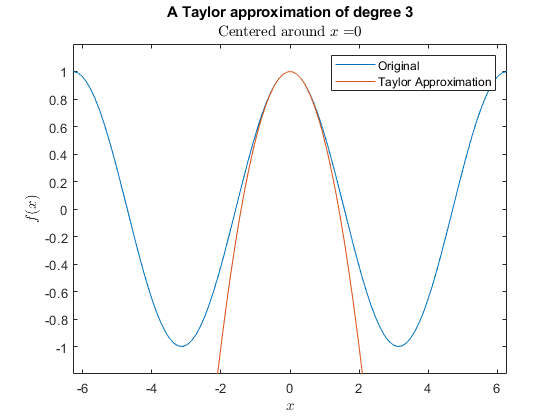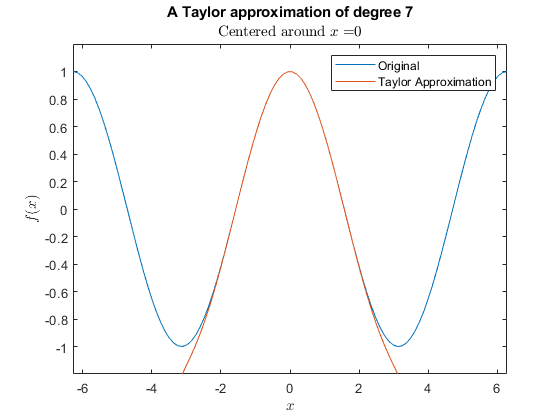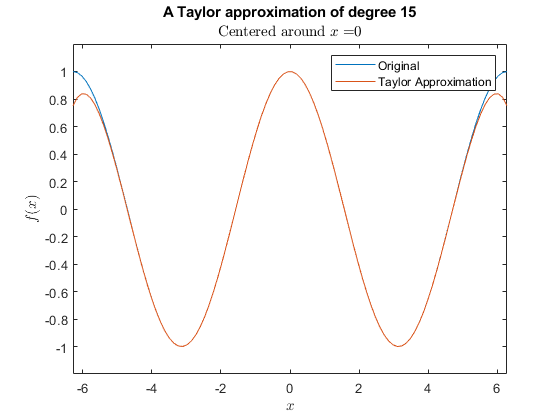

function T = ShowTaylor(fh,deg,bds,x0)
arguments
    fh function_handle
    deg (1,:) {mustBePositive,mustBeFinite,mustBeInteger}
    bds (1,2) {mustBeNumeric}
    x0 (1,1) {mustBeNumeric,mustBeFinite}
end
if length(deg) > 1
    for k = 1:length(deg)
        T = CalcTaylor(fh,deg(k),bds,x0);
        pause(0.5)
    end
else
    T = CalcTaylor(fh,deg,bds,x0);
end

end
 

function T = CalcTaylor(fh,deg,bds,x0)
% CalcTaylor calcula y traza una aproximación del 
% polinomio de Taylor fh es un identificador de función 
% deg es el grado del polinomio de Taylor bds son 
% los límites x del rango a trazar *-- -* x0 es el 
% valor central para la aproximación, x=x0
syms x
T = taylor(fh(x),x,"ExpansionPoint",x0,"Order",deg+1);
xVals = linspace(bds(1),bds(2),100);
fVals = fh(xVals);
plot(xVals,fVals);
hold on
TVals = double(subs(T,x,xVals));
plot(xVals,TVals);
hold off
title("A Taylor approximation of degree " + deg)
subtitle("Centered around $x =$" + x0,"Interpreter","latex")
xlabel("$x$","Interpreter","latex")
ylabel("$f(x)$","Interpreter","latex")
scale = double((max(fVals)-min(fVals)))*0.1;
ylim(double([min(fVals)-scale max(fVals)+scale]))
xlim(bds)
legend(["Original" "Taylor Approximation"],"Location","best")
end
